# 8.evaluateTemperatureGradient

[`[gradTx,gradTy] = evaluateTemperatureGradient(thermalresults,xq,yq)`](https://ww2.mathworks.cn/help/pde/ug/pde.steadystatethermalresults.evaluatetemperaturegradient.html#d120e41363)`:`返回`thermalresults`在`xq`和中指定的2-D点 的热模型解的温度梯度的插值`yq`。该语法对于稳态和瞬态热模型均有效。

[`[gradTx,gradTy,gradTz] = evaluateTemperatureGradient(thermalresults,xq,yq,zq)`](https://ww2.mathworks.cn/help/pde/ug/pde.steadystatethermalresults.evaluatetemperaturegradient.html#d120e41391)`:`返回所述内插的温度梯度在3- d点中指定 `xq`，`yq`和`zq`。该语法对于稳态和瞬态热模型均有效。

[`[``___``] = evaluateTemperatureGradient(thermalresults,querypoints)`](https://ww2.mathworks.cn/help/pde/ug/pde.steadystatethermalresults.evaluatetemperaturegradient.html#d120e41424)

[`[``___``] = evaluateTemperatureGradient(``___``,iT)`](https://ww2.mathworks.cn/help/pde/ug/pde.steadystatethermalresults.evaluatetemperaturegradient.html#d120e41446)

**二维稳态热模型的温度梯度**

% thermalmodel = createpde('thermal');
% R1 = [3,4,-1,1,1,-1,1,1,-1,-1]';
% g = decsg(R1,'R1',('R1')');
% geometryFromEdges(thermalmodel,g);
% pdegplot(thermalmodel,'EdgeLabels','on')
% xlim([-1.5 1.5])
% axis equal

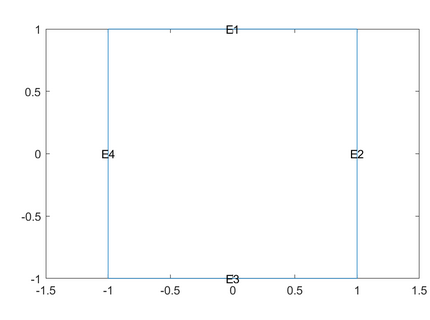

Assuming that this geometry represents an iron plate, the thermal conductivity is 79.5*W*/(*mK*).

% thermalProperties(thermalmodel,'ThermalConductivity',79.5,'Face',1);

Apply a constant temperature of 300 K to the bottom of the plate (edge 3). Also, assume that the top of the plate (edge 1) is insulated, and apply convection on the two sides of the plate (edges 2 and 4).

% thermalBC(thermalmodel,'Edge',3,'Temperature',300);
% thermalBC(thermalmodel,'Edge',1,'HeatFlux',0);
% thermalBC(thermalmodel,'Edge',[2 4], ...
%                        'ConvectionCoefficient',25, ...
%                        'AmbientTemperature',50);

Mesh the geometry and solve the problem.

% generateMesh(thermalmodel);
% results = solve(thermalmodel)
% figure;
% pdeplot(thermalmodel,'FlowData',[results.XGradients results.YGradients]);

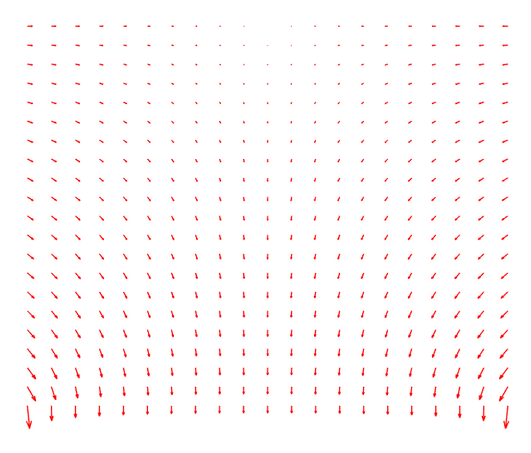

Create a grid specified by `x` and `y` coordinates, and evaluate temperature gradients to the grid.

% v = linspace(-0.5,0.5,11);
% [X,Y] = meshgrid(v);
% 
% [gradTx,gradTy] = evaluateTemperatureGradient(results,X,Y);     

Reshape the `gradTx` and `gradTy` vectors, and plot the resulting temperature gradients.

% gradTx = reshape(gradTx,size(X));
% gradTy = reshape(gradTy,size(Y));
% figure
% quiver(X,Y,gradTx,gradTy)

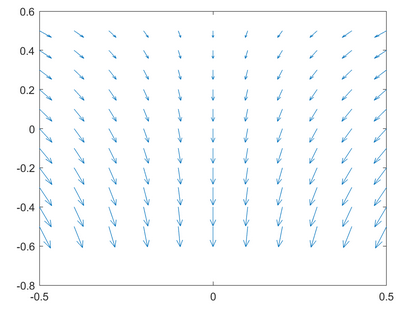

**Temperature Gradients for 3-D Steady-State Thermal Model**

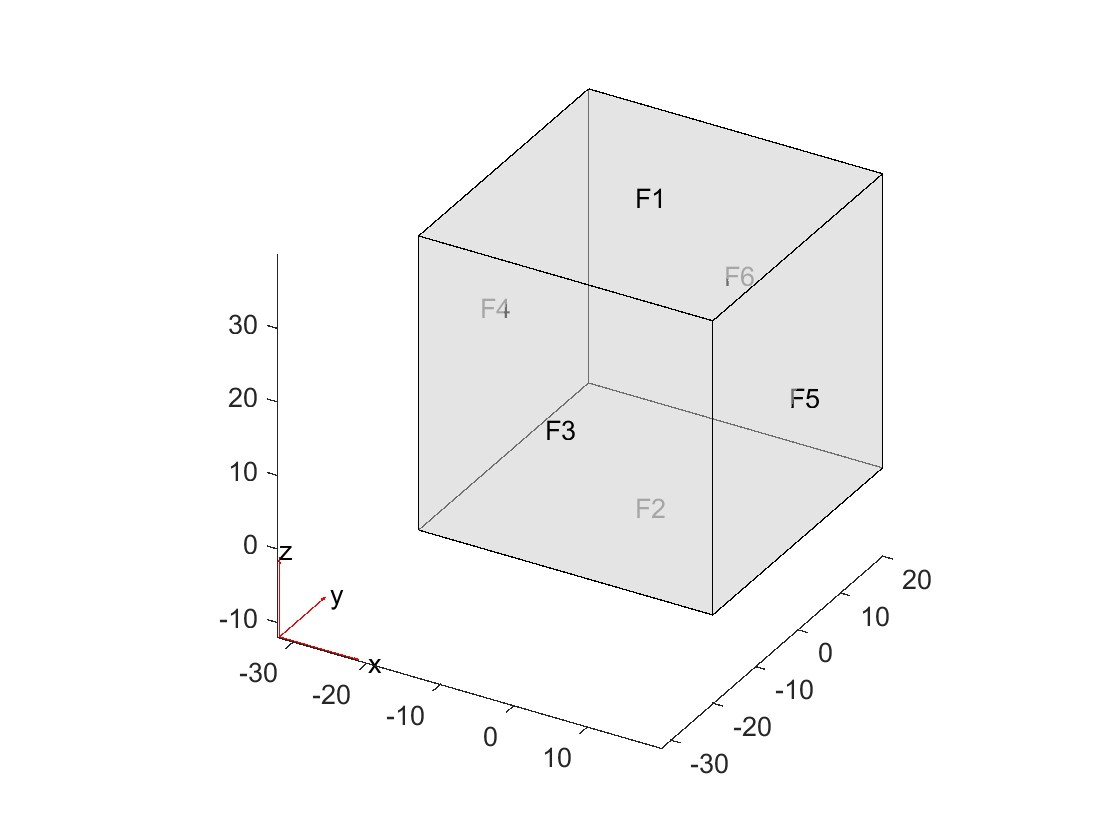

thermalmodel = createpde('thermal');
importGeometry(thermalmodel,'C:\Users\ZGY\Desktop\structure_heat_matlab\11.stl'); 
pdegplot(thermalmodel,'FaceLabel','on','FaceAlpha',0.5)
axis equal

thermalProperties(thermalmodel,'ThermalConductivity',4);
thermalBC(thermalmodel,'Face',4,'Temperature',373);
thermalBC(thermalmodel,'Face',5,'Temperature',573);
thermalBC(thermalmodel,'Face',2,'HeatFlux',-20);
generateMesh(thermalmodel);
thermalresults = solve(thermalmodel)

thermalresults =   SteadyStateThermalResults - 属性:

    Temperature: [34165×1 double]
     XGradients: [34165×1 double]
     YGradients: [34165×1 double]
     ZGradients: [34165×1 double]
           Mesh: [1×1 FEMesh]


[X,Y,Z] = meshgrid(-20:0.1:20,-20:0.1:20,0:0.1:40);

[gradTx,gradTy,gradTz] = evaluateTemperatureGradient(thermalresults,X,Y,Z);
gradTx = reshape(gradTx,size(X));
gradTy = reshape(gradTy,size(Y));
gradTz = reshape(gradTz,size(Z));

figure
quiver3(X,Y,Z,gradTx,gradTy,gradTz)
axis equal
xlabel('x')
ylabel('y')
zlabel('z')